## Why broadband phase is not a thing, illustrated by the Hilbert transform

Many papers deal with phase relationships between signals collected at different time points or at different locations, and/or different frequencies (cross-frequency coupling). Surprisingly many of these analyses are unlikely to have worked because they measured phase from broadband signals. This walkthrough uses the hilbert transform to show why broad band phase is not a thing and how not taking this seriously yield spurious results that will never ever replicate. 

% first load exampe data, make sure the data are in the current directory,
% or in the path
clear 
load('bop_107.fl40h1.E1.app2.mat') % loads our example data set (129 sensors, 2551 points,  48 trials)
size(outmat)

ans =          129        2551          48


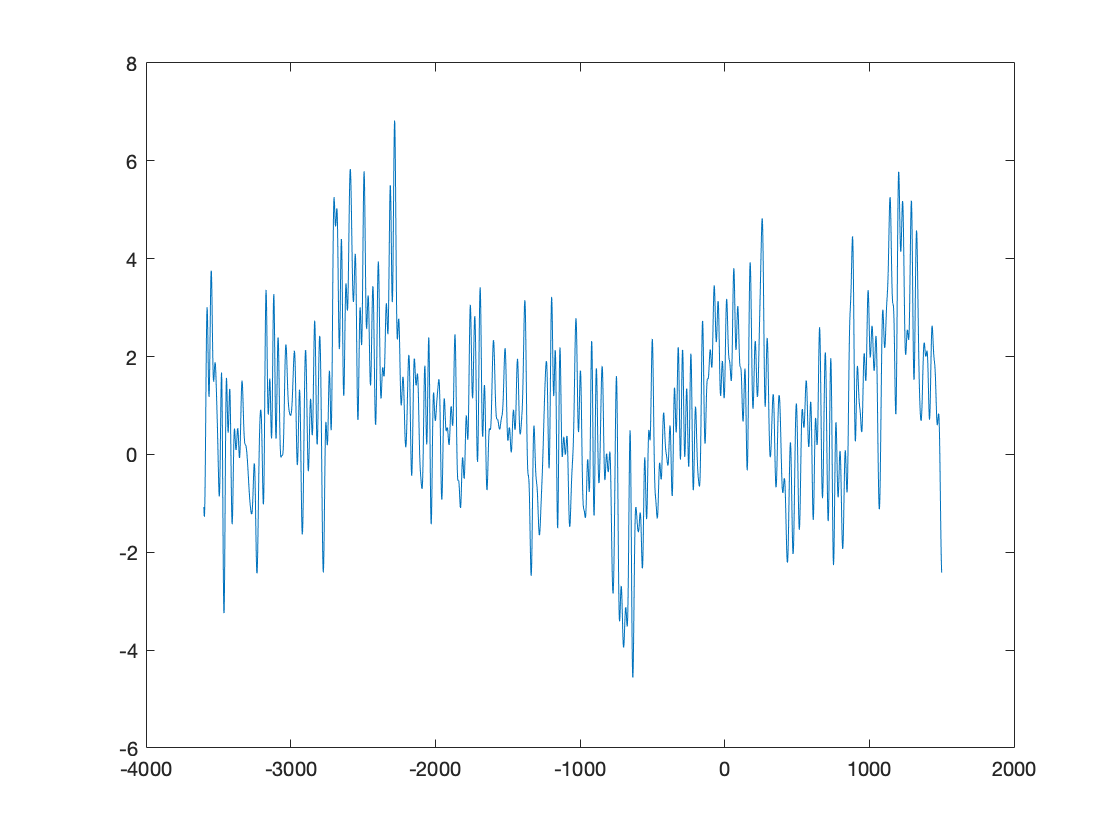

SampRate = 500; 
data = squeeze(outmat(129, :, 2))';  % the second trial, sensor Cz. 
load taxis.mat
plot(taxis, data)

Next filter the signal a bit, but not enough...let us start with 7 to 12 Hz, often used in the literature, 

[alow,blow] = butter(4, 12/250);   % 12 Hz lowpass when sampled at 500 Hz

siglow = filtfilt(alow, blow, data);

[ahigh,bhigh] = butter(2, 7/250, 'high')% 7 Hz highpass (2nd order) when sampled at 500 Hz

ahigh =     0.9397   -1.8794    0.9397


bhigh =     1.0000   -1.8757    0.8830


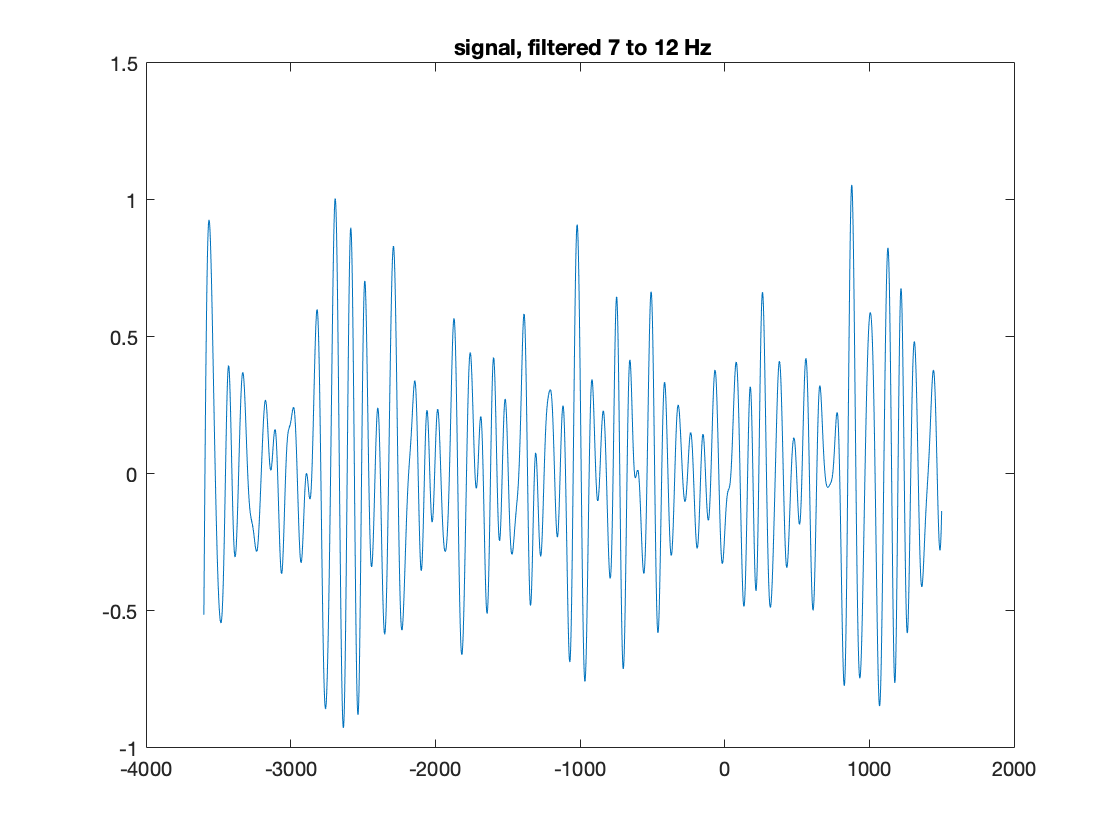


sighighlow = filtfilt(ahigh, bhigh, siglow);

figure, plot(taxis, sighighlow), title(' signal, filtered 7 to 12 Hz')

Now we apply the Hilbert transform. It estimates the local phase time-point by time point and creates a version that is shifted by 90 degrees. it is often used in CFC studies. For example 4 Hz in Canolty et al. *Science* 2016

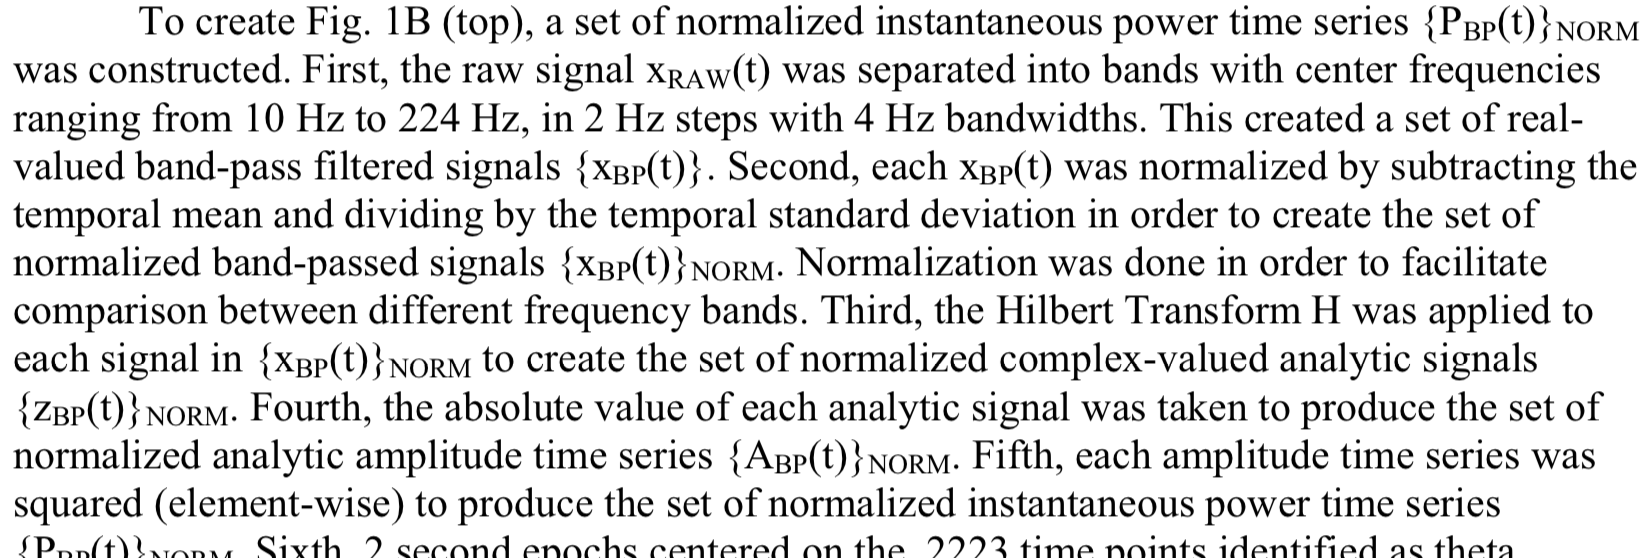

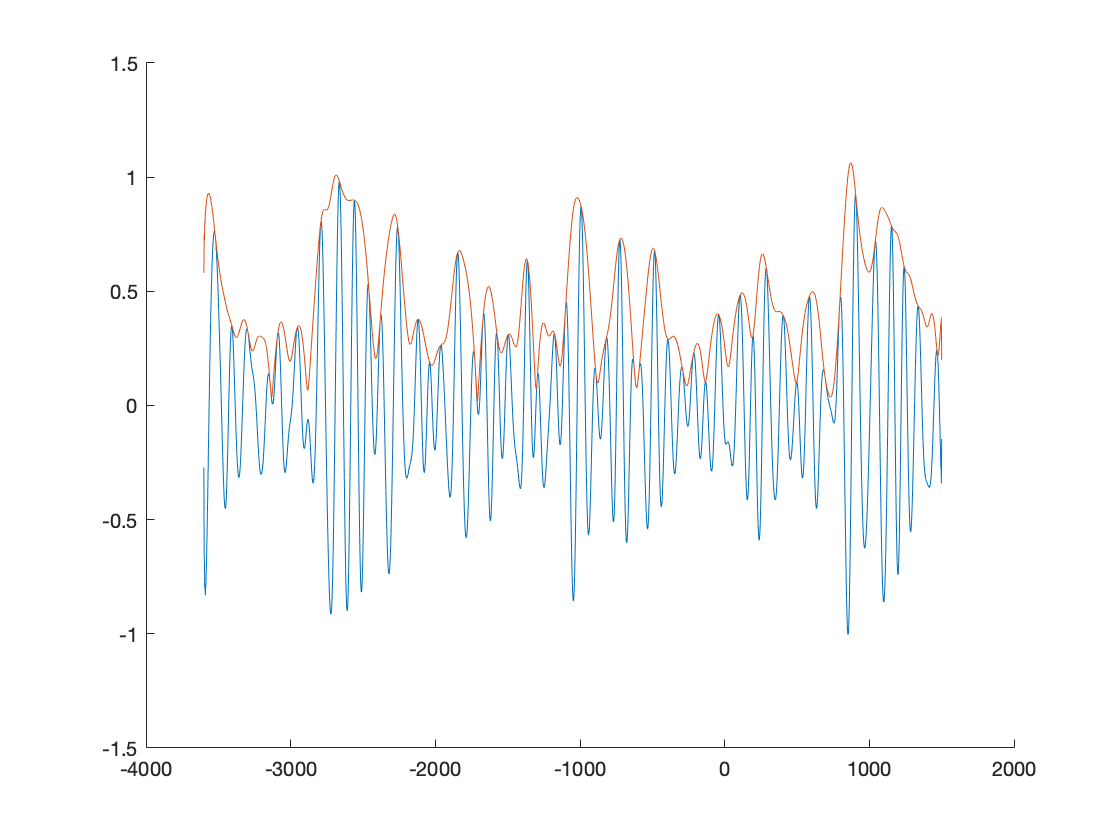

test = hilbert(sighighlow);

figure, hold on, plot(taxis, imag(test))

plot(taxis, abs(test)), hold off

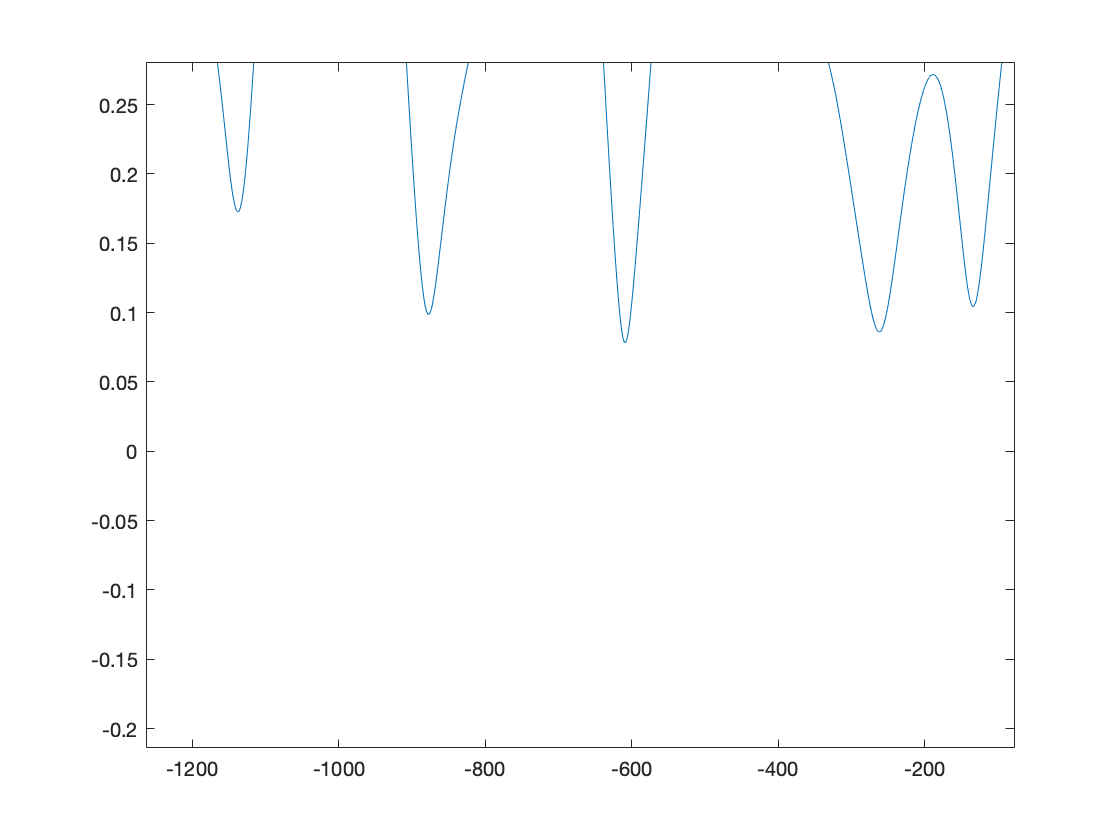


figure, plot(taxis, abs(test))
xlim([-1263 -78])
ylim([-0.214 0.280])

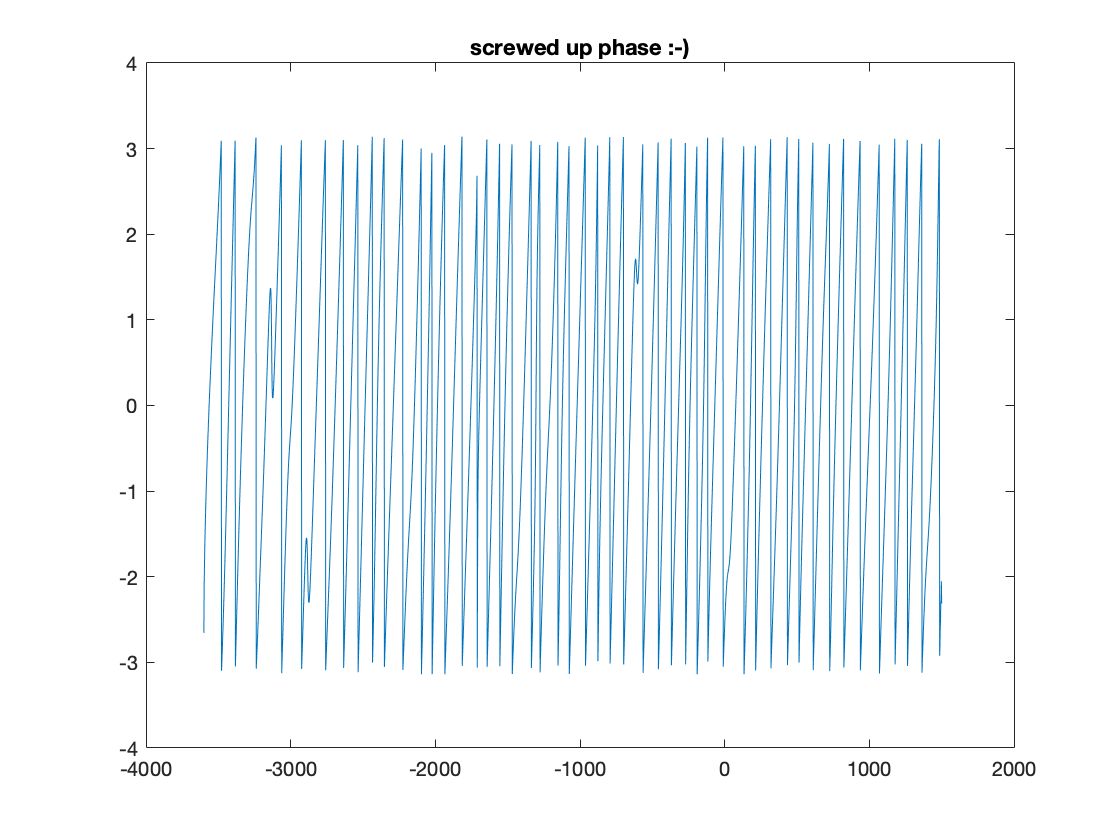


figure, plot(taxis, angle(test)), title('screwed up phase :-)')

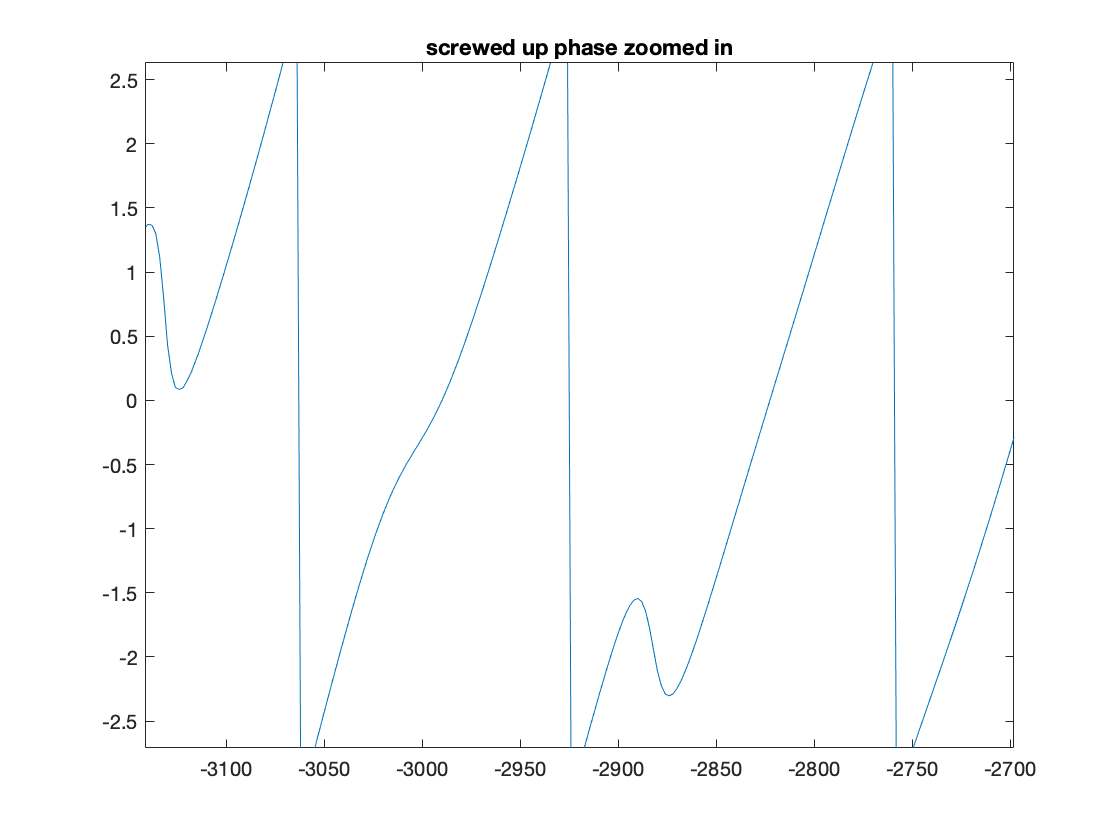


figure, plot(taxis, angle(test)), title('screwed up phase zoomed in')
xlim([-3141 -2698])
ylim([-2.71 2.63])



%now do it again, with narrow band bass :) 

[alow,blow] = butter(6, 10.5/250);   % 12 Hz lowpass when sampled at 500 Hz

siglow = filtfilt(alow, blow, data);

[ahigh,bhigh] = butter(4, 9.5/250, 'high')% 7 Hz highpass (2nd order) when sampled at 500 Hz

sighighlow = filtfilt(ahigh, bhigh, siglow);

figure(3)

plot(taxis, sighighlow), title(' new signal, hilbert analytical signal, and envelope')

test = hilbert(sighighlow);

hold on, plot(taxis, imag(test))

plot(taxis, abs(test)), hold off

figure(4)

plot(taxis, angle(test)), title('still pretty bad phase')

now do it again, with narrow band pass 


[alow,blow] = butter(6, 10/250);   % lowpass when sampled at 500 Hz

siglow = filtfilt(alow, blow, data);

[ahigh,bhigh] = butter(6, 10/250, 'high')%  highpass (2nd order) when sampled at 500 Hz

ahigh =     0.7843   -4.7058   11.7645  -15.6860   11.7645   -4.7058    0.7843


bhigh =     1.0000   -5.5145   12.6891  -15.5936   10.7933   -3.9894    0.6151


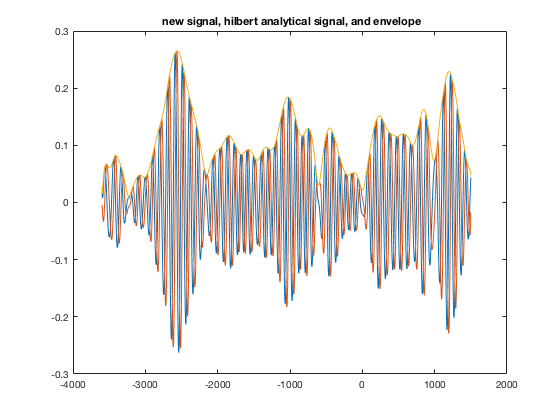


sighighlow = filtfilt(ahigh, bhigh, siglow);

figure(3)

plot(taxis, sighighlow), title(' new signal, hilbert analytical signal, and envelope')

test = hilbert(sighighlow);

hold on, plot(taxis, imag(test))

plot(taxis, abs(test)), hold off

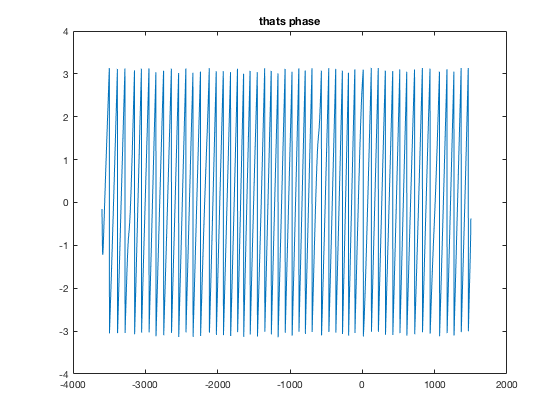


figure(4)

plot(taxis, angle(test)), title('that is smooth phase !')